## Linear Regression (Based on the [ML Coursera course](https://www.coursera.org/learn/machine-learning?utm_source=gg&utm_medium=sem&utm_campaign=07-StanfordML-ROW&utm_content=07-StanfordML-ROW&campaignid=2070742271&adgroupid=80109820241&device=c&keyword=machine%20learning%20mooc&matchtype=b&network=g&devicemodel=&adpostion=&creativeid=516962315003&hide_mobile_promo&gclid=CjwKCAjw-ZCKBhBkEiwAM4qfF9TVk9HyCyt60-JX7Y6R-2-2FO9QHcPeiOnW8eN3OpV6RY42H_adTxoCMtcQAvD_BwE))

In this exercise, you will implement linear regression and get to see it work on data.

#### Clear existing variables and confirm that your Current Folder is set correctly

clear
dir

.                       Ex1_to_do.mlx           ex1data2.txt            
..                      ex1data1.txt            gradientDescentMulti.m  



## Linear regression with one variable

The file `ex1data1.txt` contains the dataset for our linear regression problem. The first column is the initial moisture and the shrikage in the end of the test in %. A negative value for the shrinkage means expansion.

### Plotting the data

Run the code below to load the dataset from the data file into the variables X and y:

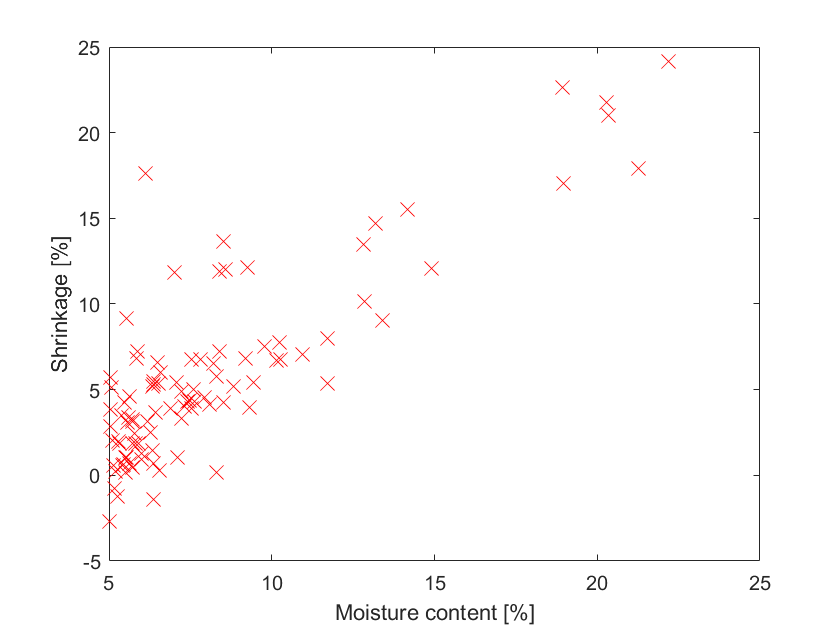

data = load('ex1data1.txt'); % read comma separated data
X = data(:, 1); y = data(:, 2);
plot(X, y, 'rx', 'MarkerSize', 10); % Plot the data
xlabel('Moisture content [%]'); % Set the x-axis label
ylabel('Shrinkage [%]'); % Set the y-axis label

### Gradient Descent

In this section, you will fit the linear regression parameters to our dataset using gradient descent. The basic idea of the gradient descent is graphically presented in the figure below. 

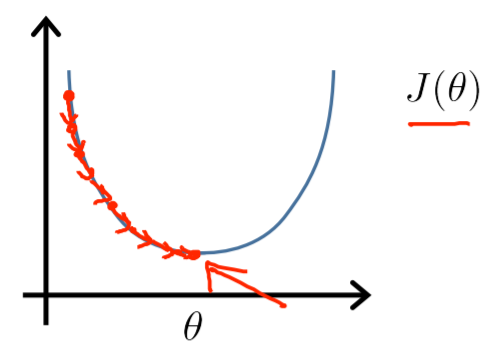

#### Update Equations

The objective of linear regression is to minimize the cost function


$$J\left(\theta \right)=\frac{1}{2m}\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \;$$


where the hypothesis $h_{\theta}(x)$ is given by the linear model


$$h_{\theta } \left(x\right)=\theta^T x=\theta_0 +\theta_1 x_1$$


The parameters of your model are the $\theta$ values. These are the values you will adjust to minimize cost $J(\theta)$. One way to do this is to use the batch gradient descent algorithm. In batch gradient descent, each iteration performs the update


$$\theta_j :=\theta_j -\alpha \frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\;\;\;\;\;\;\left(\textrm{simultaneously}\;\textrm{update}\;\theta_{j\;} \;\textrm{for}\;\textrm{all}\;j\right)$$


With each step of gradient descent, your parameters $j$ come closer to the optimal values that will achieve the lowest cost $J(\theta)$.

**Implementation Note:** We store each example as a row in the the `X` matrix in MATLAB. To take into account the intercept term ($\theta_0$), we add an additional first column to `X` and set it to all ones. This allows us to treat $\theta_0$ as simply another 'feature'.

#### Implementation

In this script, we have already set up the data for linear regression. In the following lines, we add another dimension to our data to accommodate the $\theta_0$ intercept term. Run the code below to initialize the parameters to 0 and the learning rate `alpha` to 0.01. 


$$h_{\theta } \left(x\right)=\theta^T x=\theta_0 +\theta_1 x_1$$


m = length(X); % number of training examples
X = [ones(m,1),data(:,1)]; % Add a column of ones to x
theta = zeros(2, 1); % initialize fitting parameters
iterations = 1500;
alpha = 0.01;

#### Computing the cost $\mathit{\mathbf{J}}\left(\theta \right)$

As you perform gradient descent to minimize the cost function $J\left(\theta \right)$, it is helpful to monitor the convergence by computing the cost. In this section, we will implement a function to calculate $J\left(\theta \right)$ so we can check the convergence of your gradient descent implementation.

    Our next task is to complete the code in the file `computeCost.m`, which is a function that computes $J\left(\theta \right)$. As you are doing this, remember that the variables `X` and `y` are not scalar values, but matrices whose rows represent the examples from the training set.

    Once you have completed the function definition, run this section. The code below will call `computeCost` once using $\theta$ initialized to zeros, and you will see the cost printed to the screen. You should expect to see a cost of 32.07 for the first output below:


$$J\left(\theta \right)=\frac{1}{2m}\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \;$$



$$h_{\theta } \left(x\right)=\theta^T x=\theta_0 +\theta_1 x_1$$


% Compute and display initial cost with theta all zeros
h = X*theta;
J_sum = 0.5/m*sum((h-y).^2) % method 1

J_sum = 4.4801

%J_dot = 0.5/m*(h-y)'*(h-y)  % method 2
%J_norm = 0.5/m*norm(h-y)^2   % method 3

Next we compute cost again, this time with non-zero `theta` values as an additional test. We should expect to see an output of 54.24 below:

% Compute and display initial cost with non-zero theta
theta=[-1; 2];
h = X*theta;
J_check = 0.5/m*norm(h-y)^2

J_check = 54.2425

#### Gradient descent

Next, we will implement gradient descent. 

    As we program, we need to make sure we understand what we are trying to optimize and what is being updated. Keep in mind that the cost $J\left(\theta \right)$ is parameterized by the vector $\theta$, not $X$ and $y$. That is, we minimize the value of $J\left(\theta \right)$ by changing the values of the vector $\theta$, not by changing $X$ or $y$. 

A good way to verify that gradient descent is working correctly is to look at the value of `J` and check that it is decreasing with each step. 


$$\theta_j :=\theta_j -\alpha \frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\;\;\;\;\;\;\left(\textrm{simultaneously}\;\textrm{update}\;\theta_{j\;} \;\textrm{for}\;\textrm{all}\;j\right)$$



$$h_{\theta } \left(x\right)=\theta^T x=\theta_0 +\theta_1 x_1$$


% Run gradient descent:
% Compute theta
m = length(y); % number of training examples
J_history = zeros(iterations, 1);

for iter = 1:iterations
    
     h = X*theta;
     summa = (h-y)'*X;
     theta = theta - alpha/m*summa';
     % Save the cost J in every iteration    
     J = 0.5/m*norm(X*theta-y)^2;
     J_history(iter) = J;

end

% Print theta to screen
% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f',theta(1),theta(2))

Theta computed from gradient descent:
-3.709689,
1.174339

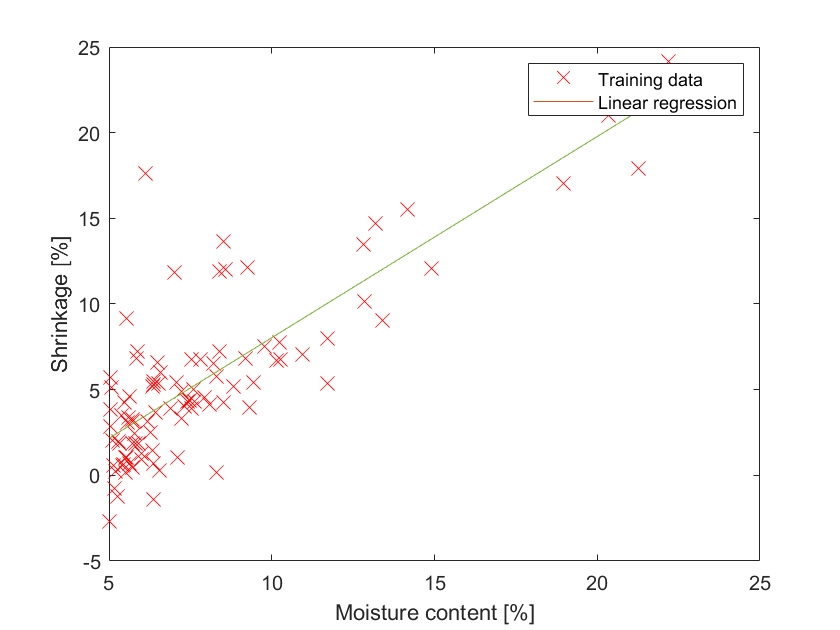


% Plot the linear fit
hold on; % keep previous plot visible
plot(X(:,2), X*theta, '-')
legend('Training data', 'Linear regression')
hold off % don't overlay any more plots on this figure


% Predict shrinkage value for the moisture of 3.5 %
predict = [1, 3.5] *theta;
fprintf('For moisture content  = 3.5 percent, we predict shrinkage of %f\n', predict);

For moisture content  = 3.5 percent, we predict shrinkage of 0.400496


    Note the way that the lines above use matrix multiplication, rather than explicit summation or looping, to calculate the predictions. 

### Debugging

Here are some things to keep in mind as you implement gradient descent: 

- MATLAB array indices start from one, not zero. If you're storing $\theta_0$ and $\theta_1$ in a vector called `theta`, the values will be `theta(1)` and `theta(2)`.

- If you are seeing many errors at runtime, inspect your matrix operations to make sure that you're adding and multiplying matrices of compatible dimensions. Printing the dimensions of variables with the `size` command will help you debug.

- By default, MATLAB interprets math operators to be matrix operators. This is a common source of size incompatibility errors. If you don't want matrix multiplication, you need to add the "dot" notation to specify this to MATLAB. For example, `A*B` does a matrix multiply, while `A.*B` does an element-wise multiplication.

### 2.4 Visualizing $J(\theta)$

To understand the cost function $J(\theta)$ better, we will now plot the cost over a 2-dimensional grid of $\theta_0$ and $\theta_1$ values. 

% Visualizing J(theta_0, theta_1):
% Grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);

% initialize J_vals to a matrix of 0's
J_vals = zeros(length(theta0_vals), length(theta1_vals));

% Fill out J_vals
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
 	t = [theta0_vals(i); theta1_vals(j)];    
         J_vals(i,j) = 0.5/m*norm(X*t-y)^2;
    end
end

    After the code above is executed, you will have a 2-D array of $J(\theta)$ values. The code below will then use these values to produce surface and contour plots of $J(\theta)$ using the `surf` and `contour` commands. Run the code in this section now. The resulting plots should look something like the figure below.

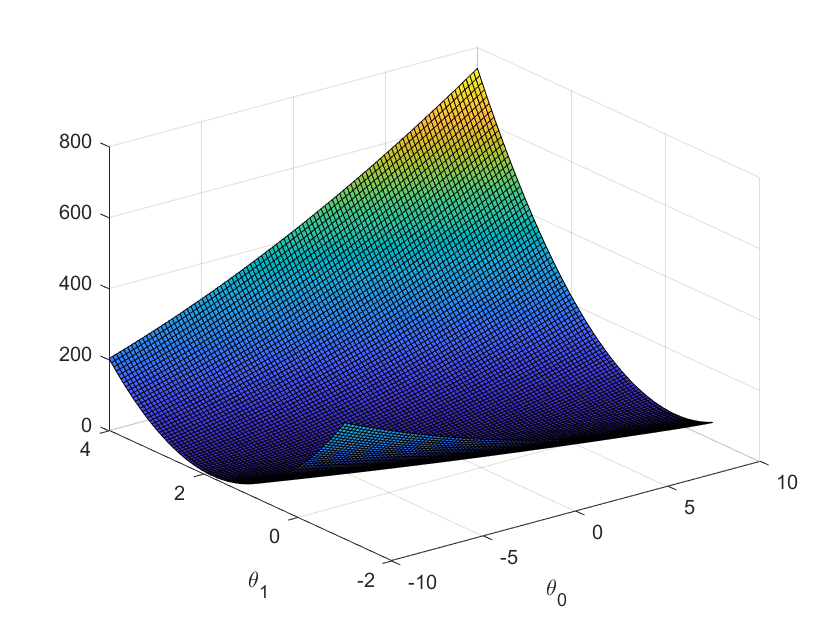

% Because of the way meshgrids work in the surf command, we need to 
% transpose J_vals before calling surf, or else the axes will be flipped
J_vals = J_vals';

% Surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); ylabel('\theta_1');

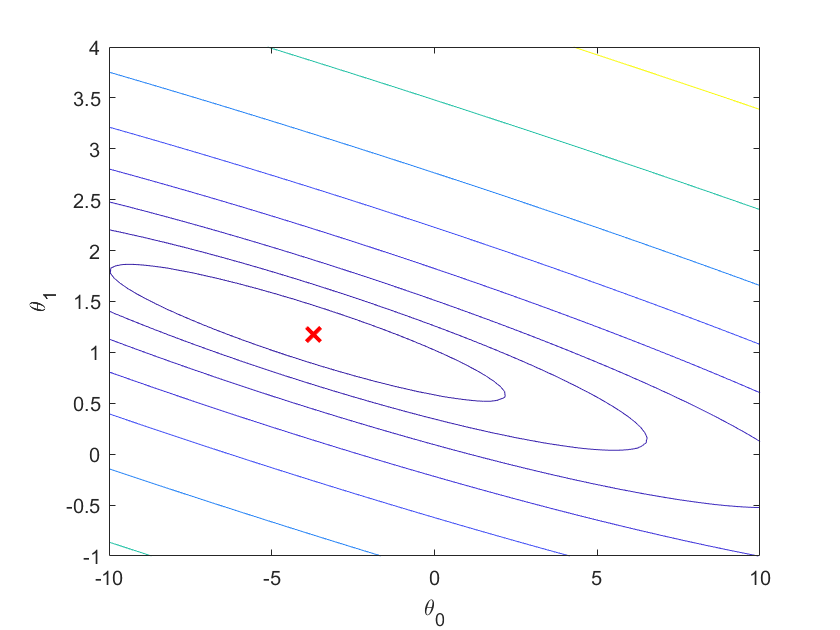

% Contour plot
figure;
% Plot J_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(theta(1), theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
hold off;

    The purpose of these graphs is to show you that how $J(\theta)$ varies with changes in $\theta_0$ and $\theta_1$. The cost function $J(\theta)$ is bowl-shaped and has a global mininum. (This is easier to see in the contour plot than in the 3D surface plot). This minimum is the optimal point for $\theta_0$ and $\theta_1$, and each step of gradient descent moves closer to this point.

## Linear regression with multiple variables

In this part, we will implement linear regression with multiple variables to predict the stiffness of a spring. 

    The file `ex1data2.txt` contains a training set of stiffnesses. The first column is the cross-section of the spring wire, the second column is the diameter, and the third column is the stiffness. Run this section now to preview the data.

% Load Data
data = load('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);

% Print out some data points
% First 10 examples from the dataset
fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) y(1:10,:)]');

 x = [2104 3], y = 399900 
 x = [1600 3], y = 329900 
 x = [2400 3], y = 369000 
 x = [1416 2], y = 232000 
 x = [3000 4], y = 539900 
 x = [1985 4], y = 299900 
 x = [1534 3], y = 314900 
 x = [1427 3], y = 198999 
 x = [1380 3], y = 212000 
 x = [1494 3], y = 242500 


### Feature Normalization

This section of the script will start by loading and displaying some values from this dataset. By looking at the values, note that diameters are about 1000 times the cross-section area. When features differ by orders of magnitude, first performing feature scaling can make gradient descent converge much more quickly.

    We need to normalize the features:

- Subtract the mean value of each feature from the dataset.

- After subtracting the mean, additionally scale (divide) the feature values by their respective "standard deviations".

    You will do this for all the features and your code should work with datasets of all sizes (any number of features / examples). Note that each column of the matrix `X` corresponds to one feature. 

% Scale features and set them to zero mean
n = length(X(1,:)); % number of features
mu = zeros(n,1);
sigma = zeros(n,1);
for i = 1:n
     mu(i) = mean(X(:,i));  % mean value
     sigma(i) = std(X(:,i)); % standart deviation
     X(:,i) = (X(:,i)-mu(i))/sigma(i);
end

**Implementation Note: **When normalizing the features, it is important to store the values used for normalization - the mean value and the standard deviation used for the computations. After learning the parameters from the model, we often want to predict the stiffness of the springs we have not seen before. Given a new `x` value (cross section area and diameter), we must first normalize `x` using the mean and standard deviation that we had previously computed from the training set.

#### Add the bias term

Now that we have normailzed the features, we again add a column of ones corresponding to $\theta_0$ to the data matrix `X``.`


$$h_{\theta } \left(x\right)=\theta^T x=\theta_0 +\theta_1 x_1 +\theta_2 x_2$$


% Add intercept term to X
m = length(X(:,1)); % number of data sets
X = [ones(m, 1) X];

### Gradient Descent

Previously, we implemented gradient descent on a univariate regression problem. The only difference now is that there is one more feature in the matrix `X`. The hypothesis function and the batch gradient descent update rule remain unchanged.

**Implementation Note: **In the multivariate case, the cost function can also be written in the following vectorized form:


$$J(\theta)=\frac{1}{2m}\left(X\theta-\vec{y}\right)^T\left(X\theta-\vec{y}\right)$$


where


$$X=\left\lbrack \begin{array}{c}
{-\;\left(x^{\left(1\right)} \right)}^T -\\
{-\;\left(x^{\left(2\right)} \right)}^T -\\
\vdots \;\\
{-\;\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\vec{y} =\left\lbrack \begin{array}{c}
y^{\left(1\right)} \\
y^{\left(2\right)} \\
\vdots \;\\
y^{\left(m\right)} 
\end{array}\right\rbrack$$


The vectorized version is efficient when you're working with numerical computing tools like MATLAB.

% Run gradient descent
% Choose some alpha value
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
m = length(y); % number of training examples
J_history = zeros(num_iters, 1);

for iter = 1:num_iters

    % Instructions: Perform a single gradient step on the parameter vector
    %               theta. 
    %
    % Hint: While debugging, it can be useful to print out the values
    %       of the cost function and gradient here.
    %
    
     h = X*theta;
     summa = (h-y)'*X;
     theta = theta - alpha/m*summa';
     % ============================================================
%
     % Save the cost J in every iteration    
     J_history(iter) = 0.5/m*norm(X*theta-y)^2;

end

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

Theta computed from gradient descent:
340412.659574
110631.048958
-6649.472950

Finally, we should complete and run the code below to predict the stiffness of a spring with an area of 1650 mm^2, and diameter 3 cm using the value of `theta` obtained above. 

% Estimate the stiffness
stiff = [1, (1650-mu(1))/sigma(1), (3-mu(2))/sigma(2)] *theta; % Stiffness formula

fprintf('Predicted stiffness of a spring with an area of 1650 mm^2, and diameter 3 cm (using gradient descent):\n %f [Pa]', stiff);

Predicted stiffness of a spring with an area of 1650 mm^2, and diameter 3 cm (using gradient descent):
 293081.464622 [Pa]

#### **Selecting learning rates**

In this part of the exercise, you will get to try out different learning rates for the dataset and find a learning rate that converges quickly. You can change the learning rate by modifying the code below and changing the part of the code that sets the learning rate.

    The code below will run gradient descent for about 50 iterations at the chosen learning rate. The function should also return the history of $J(\theta)$ values in a vector `J`. After the last iteration, the code plots the `J` values against the number of the iterations. If you picked a learning rate within a good range, your plot should look similar Figure 4 below. 

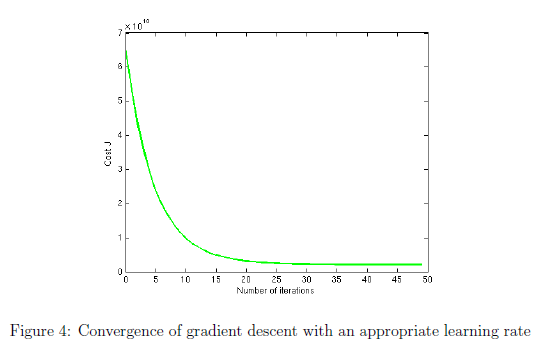

    If your graph looks very different, especially if your value of $J(\theta)$ increases or even blows up, use the control to adjust your learning rate and try again. We recommend trying values of the learning rate on a log-scale, at multiplicative steps of about 3 times the previous value (i.e., 0.3, 0.1, 0.03, 0.01 and so on). You may also want to adjust the number of iterations you are running if that will help you see the overall trend in the curve.

**Implementation Note:** If your learning rate is too large, $J(\theta)$ can diverge and 'blow up', resulting in values which are too large for computer calculations. In these situations, MATLAB will tend to return `NaNs`. `NaN` stands for 'not a number' and is often caused by undefined operations that involve $\pm \;\infty$.

**MATLAB Tip:** To compare how different learning learning rates affect convergence, it's helpful to plot `J` for several learning rates on the same figure. In MATLAB, this can be done by performing gradient descent multiple times with a `hold on` command between plots. Make sure to use the `hold off` command when you are done plotting in that figure. Concretely, if you've tried three different values of `alpha` (you should probably try more values than this) and stored the costs in `J1`, `J2` and `J3`, you can use the following commands to plot them on the same figure:

    The final arguments `'b'`,`'r'`, and `'k``'` specify different colors for the plots. If desired, you can use this technique and adapt the code below to plot multiple convergence histories in the same plot. 

% Run gradient descent:
% Choose some alpha value
alpha = 1;
num_iters = 50;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
tic
[~, J_history] = gradientDescentMulti(X, y, theta, alpha, num_iters);
toc

Elapsed time is 0.003785 seconds.


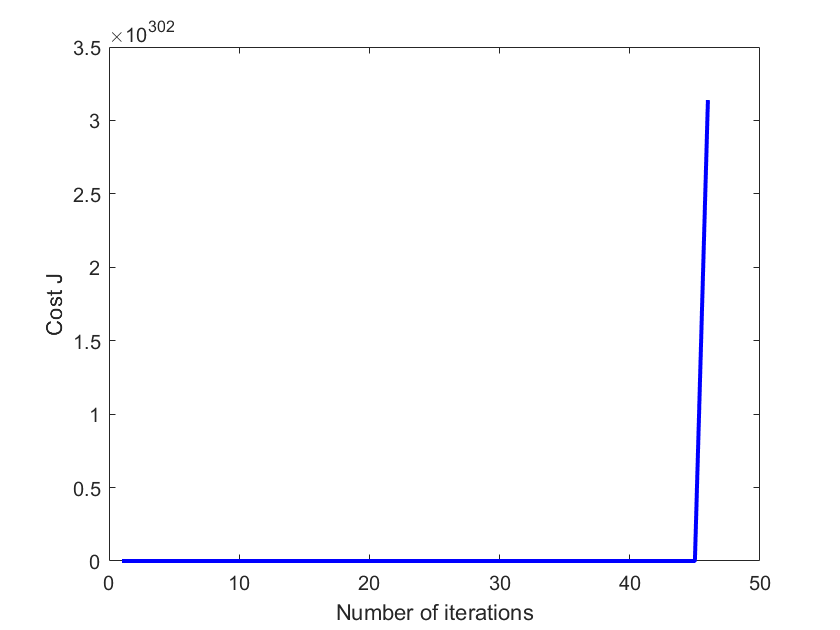

% Plot the convergence graph
plot(1:num_iters, J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');

Notice the changes in the convergence curves as the learning rate changes. With a small learning rate, you should find that gradient descent takes a very long time to converge to the optimal value. Conversely, with a large learning rate, gradient descent might not converge or might even diverge! 

    Using the best learning rate that we found, run the section of code below, which will run gradient descent until convergence to find the final values of $\theta$. Next, use this value of $\theta$ to predict the stiffness of a spring with an area of 1650 mm^2, and diameter 3 cm. You will use value later to check your implementation of the normal equations. Don't forget to normalize your features when you make this prediction!

% Run gradient descent
% Replace the value of alpha below best alpha value you found above
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))
J = 0.5/m*norm(X*theta-y)^2;
fprintf('The minimized cost function \n%e', J);
% Estimate the stiffness of a spring with an area of 1650 mm^2, and diameter 3 cm. You can use the same
% code you entered ealier to predict the stiffness

stiff = [1, (1650-mu(1))/sigma(1), (3-mu(2))/sigma(2)] *theta; % Stiffness formula here

fprintf('Predicted stiffness of a spring with an area of 1650 mm^2, and diameter 3 cm (using gradient descent):\n %f [Pa]', stiff);

### Normal Equations

The closed-form solution to linear regression is


$$\theta = \left(X^T X\right)^{-1} X^T \vec{y} $$


    Using this formula does not require any feature scaling, and you will get an exact solution in one calculation: there is no "loop until convergence" like in gradient descent.

% Solve with normal equations:
% Load Data
data = csvread('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Add intercept term to X
X = [ones(m, 1) X];

% Calculate the parameters from the normal equation
% theta_norm=pinv(X'*X)*X'*y
% Calculate the parameters using single value decomposition
[U,S,V] = svd(X,'econ');
% theta_svd = V*pinv(S)*U'*y % Least-square fit
% Display normal equation's result
fprintf('Theta computed from the normal equations:\n%f\n%f\n%f', theta_norm(1),theta_norm(2),theta_norm(3));
% J = 0.5/m*norm(X*theta_norm-y)^2;
fprintf('The minimized cost function \n%e', J);

% stiff = [1, 1650, 3] *theta_norm; % Stiffness formula here

% ============================================================

fprintf('Predicted stiffness of a spring with an area of 1650 mm^2, and diameter 3 cm (using normal equation):\n %f [Pa]', stiff);

# Linear Regression with built-in Matlab tools

## Load and preview the data

We will use the same data. After a `table` is displayed as output you can perform basic sort and filter operations on a given columns as follows:

- Hover the mouse pointer over the desired variable name (column heading)

- Click on the down arrow when it appears

- Choose the desired sort option to sort all rows in the table based on the value in that variable OR

- Enter a specific range in the boxes provided to select only rows whose value for the selected variable falls inside that range

- The MATLAB code required to perform 3 and/or 4 is automatically displayed below the `table`. If desired, the code can be copied to the clipboard or added to the script using the 'Copy' and 'Update' code buttons.

After running this section, experiment with sorting and filtering the data `table` below. (Since we want to use all the observations in `data`, there is no need to copy the code or add it to the script.)

clear;
% Load Data
data = readtable('ex1data2.txt');
% methods(data) % list all methods applicable to data
% data.Properties.VariableNames = {'Area', 'Diameter', 'Stiffness'}

## Fit a linear model using `fitlm` and estimate stiffness

The `fitlm` function can be used to fit a regression model with multiple variables as well. Note that the last column (variable) in the input table is considered the response variable by `fitlm` by default while all other variables are considered predictors. A different response variable can be specified, if desired- see the `fitlm` documentation for more information. Run this section to fit a linear model, display the model the coefficients, and predict the stiffness. Compare with results with previous case.

linMdl = fitlm(data);
% theta = linMdl.Coefficients.Estimate;
fprintf('Theta computed by fitlm: [%f; %f]',theta(1),theta(2))
% stiff = predict(linMdl,[1650 3]); % Stiffness formula here
fprintf('Predicted stiffness of a spring with an area of 1650 mm^2, and diameter 3 cm (using build-in tools):\n %f [Pa]', stiff);

The linear regression paves the way to polynomial regression. In fact, it is just a particular case of the linear regression.